# **Q1d**

m = 10;
g = 9.8;
b = 1.5;

sys = tf([m*g], [m, b, 0])


sys =
 
        98
  --------------
  10 s^2 + 1.5 s
 
Continuous-time transfer function.



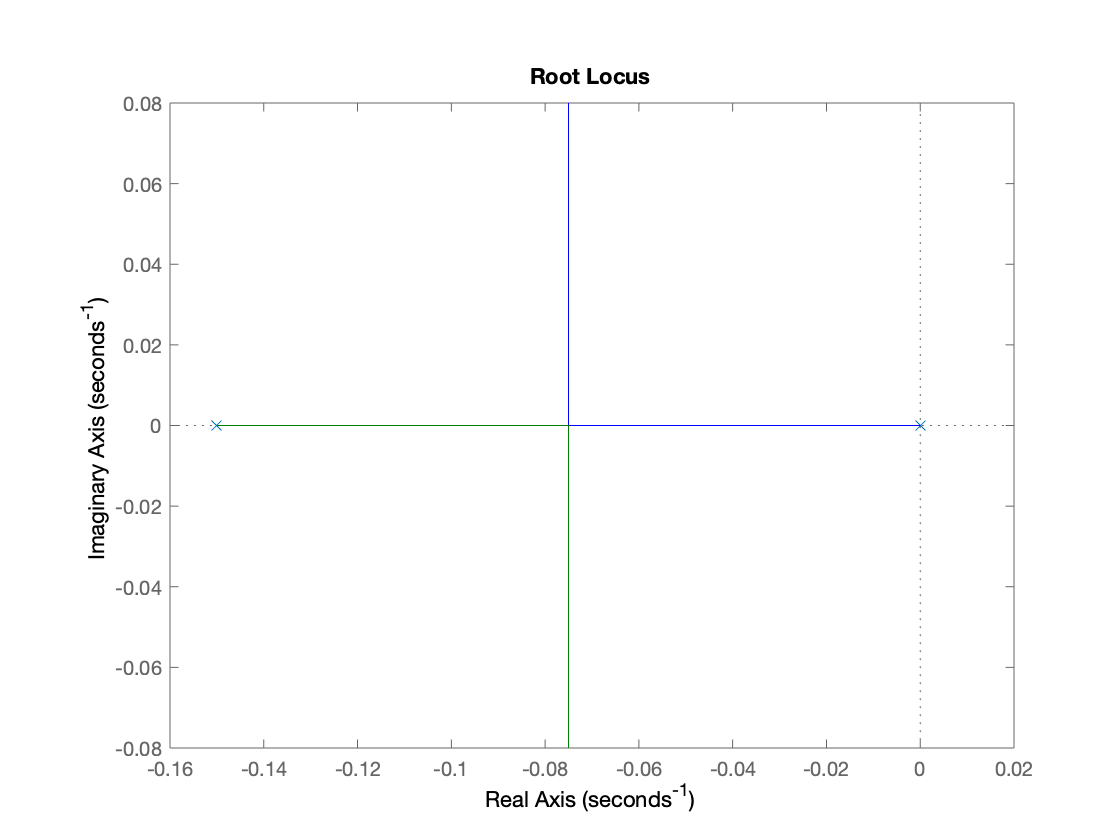

rlocus(sys)

To get step responses for K = 0 and K = 0.000574, drag the root locus in sisotool:

sisotool(sys)

# **Q1e**

sys005 = 0.05*tf([m*g], [m, b, 0])


sys005 =
 
       4.9
  --------------
  10 s^2 + 1.5 s
 
Continuous-time transfer function.



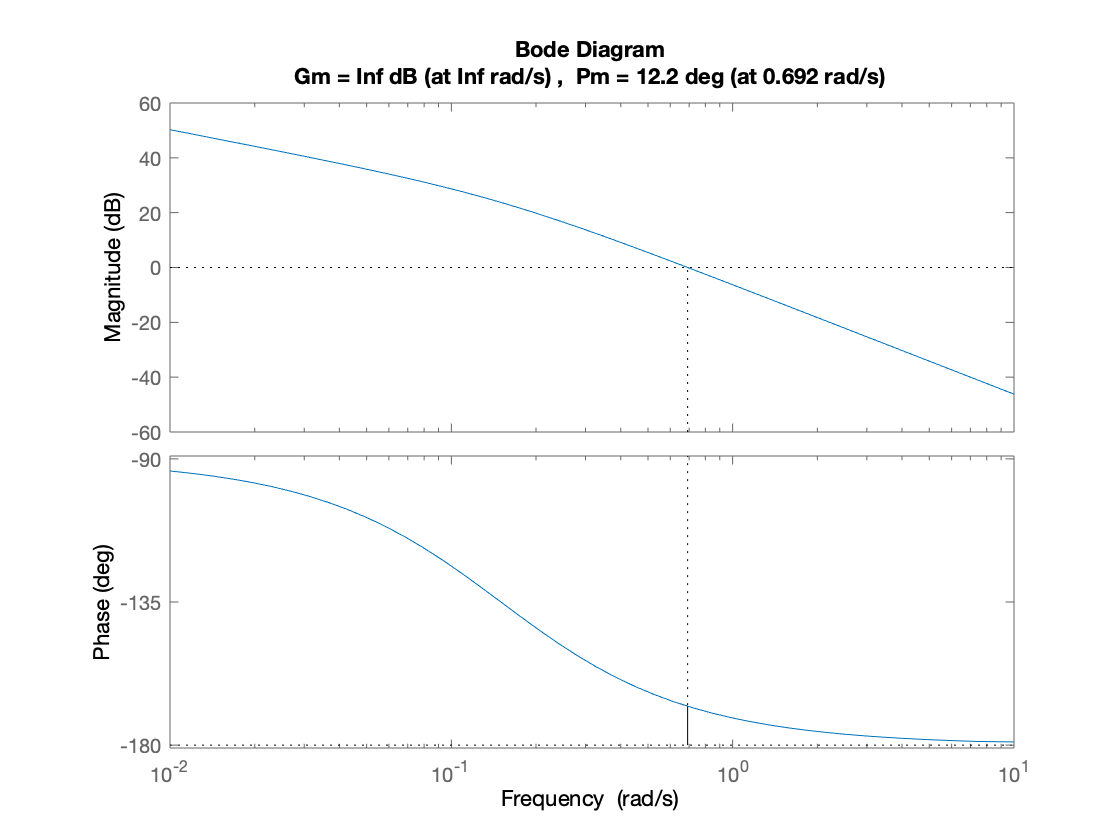

margin(sys005)

T = feedback(0.05*sys,1)


T =
 
          4.9
  --------------------
  10 s^2 + 1.5 s + 4.9
 
Continuous-time transfer function.



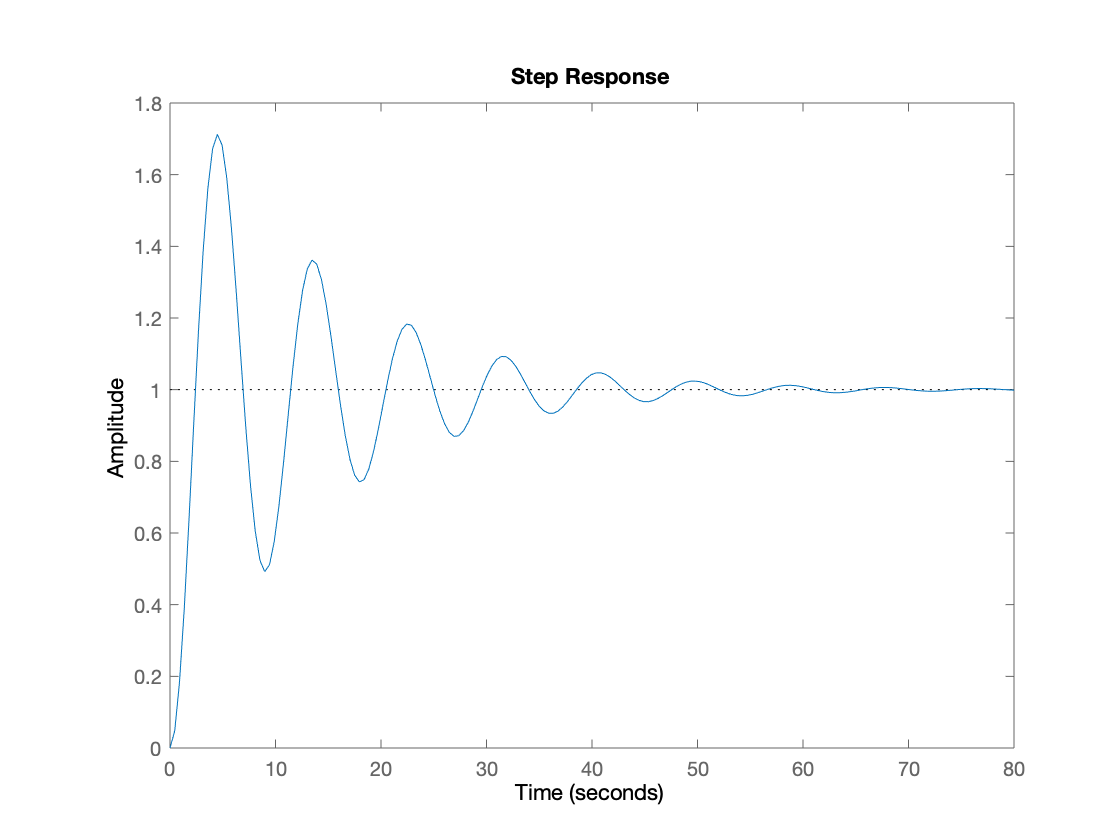

step(T)

stepinfo(T)

ans = struct with fields:
        RiseTime: 1.6196
    SettlingTime: 50.4972
     SettlingMin: 0.4922
     SettlingMax: 1.7127
       Overshoot: 71.2686
      Undershoot: 0
            Peak: 1.7127
        PeakTime: 4.4880


Lead compensator:


$$k\frac{s+z}{s+p}$$



$$w_c =\frac{\left(w_c +a\right)+\left(w_c -a\right)}{2}$$


Let a = 0.3:

z = 0.692 - 0.3;
p = 0.692 + 0.3;

Lead gain:

LG = abs((z + 0.692i)/(p + 0.692i));
K = 0.05/LG

K = 0.0760

lead_cmp = K*tf([1,z],[1,p])


lead_cmp =
 
  0.07604 s + 0.02981
  -------------------
       s + 0.992
 
Continuous-time transfer function.



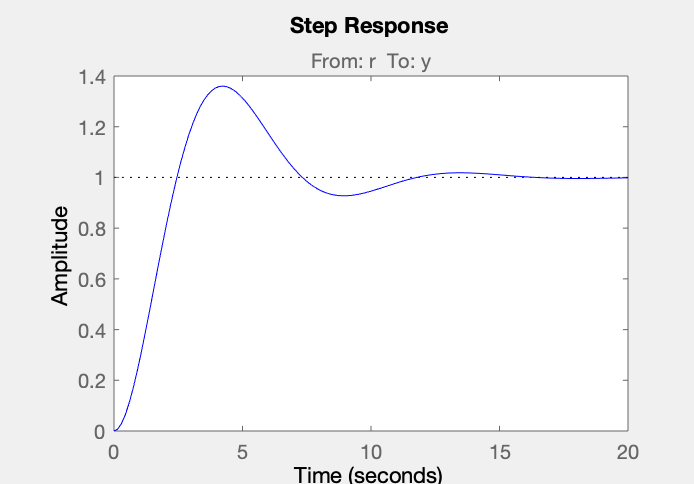

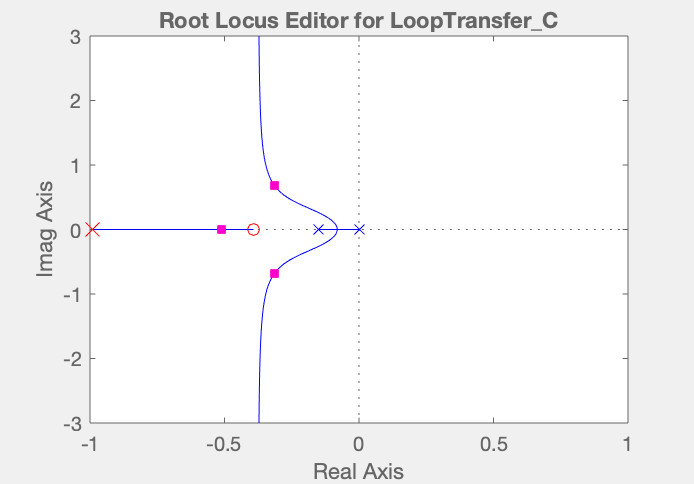

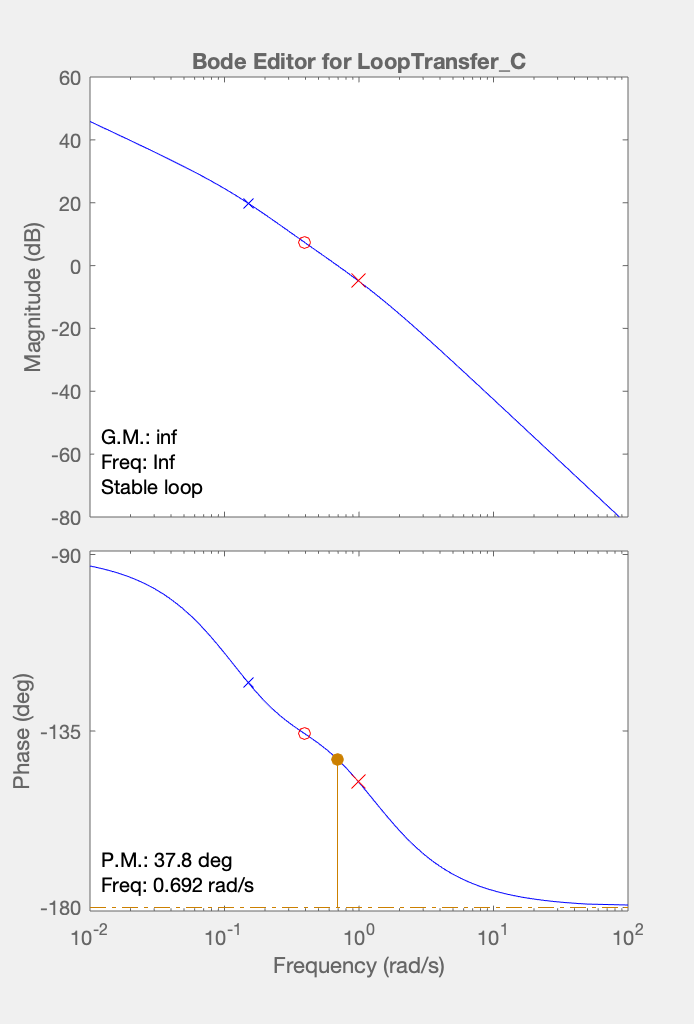

sisotool(sys, lead_cmp)